## **初始化 清除内存**

clear
clc
close all

## 参数设置

step = 1;    % 步长
eta = 0.95;  % 缩短步长比值
c = 5;  % 步长比值
n = 100; % 迭代次数
k = 20; %数组维度


## 构建数组

x = rands(k,1);
xbest = x;
fbest = f(x);
originStore = f(x);
fbestStore = fbest;
disp(['0: ','xbest:[',num2str(xbest'),'] ','fbest:[',num2str(fbest),']']);

0: xbest:[-0.71984    -0.49444     0.11416    0.019691     0.95203     0.55983     -0.5141    -0.82264     0.60689     0.40639      0.8513    -0.19503    -0.48965     0.47986    -0.18877    0.078454    -0.68249     0.93923     0.13112    -0.73972] fbest:[2.5802]


## 遍历部分

for i = 1:n
    d0 = step/c;
    dir = rands(k,1);
    dir = dir / norm(dir);
    xl = x + d0 * dir / 2;
    xr = x - d0 * dir / 2;
    fl = f(xl);
    fr = f(xr);
    x = x - step * dir * sign(fl - fr);
    temp = f(x);
    if (temp < fbest)
        fbest = temp;
        xbest = x;
    end
    originStore = [originStore ; temp];
    fbestStore = [fbestStore ; fbest];
    step = step * eta;
    disp([num2str(i),': xbest:[',num2str(xbest'),'] ','fbest:[',fbest,']']);
end

1: xbest:[-0.71984    -0.49444     0.11416    0.019691     0.95203     0.55983     -0.5141    -0.82264     0.60689     0.40639      0.8513    -0.19503    -0.48965     0.47986    -0.18877    0.078454    -0.68249     0.93923     0.13112    -0.73972] fbest:[]
2: xbest:[-0.71984    -0.49444     0.11416    0.019691     0.95203     0.55983     -0.5141    -0.82264     0.60689     0.40639      0.8513    -0.19503    -0.48965     0.47986    -0.18877    0.078454    -0.68249     0.93923     0.13112    -0.73972] fbest:[]
3: xbest:[-0.71984    -0.49444     0.11416    0.019691     0.95203     0.55983     -0.5141    -0.82264     0.60689     0.40639      0.8513    -0.19503    -0.48965     0.47986    -0.18877    0.078454    -0.68249     0.93923     0.13112    -0.73972] fbest:[]
4: xbest:[-0.71984    -0.49444     0.11416    0.019691     0.95203     0.55983     -0.5141    -0.82264     0.60689     0.40639      0.8513    -0.19503    -0.48965     0.47986    -0.18877    0.078454    -0.68249     0.93923     0.

## 画图

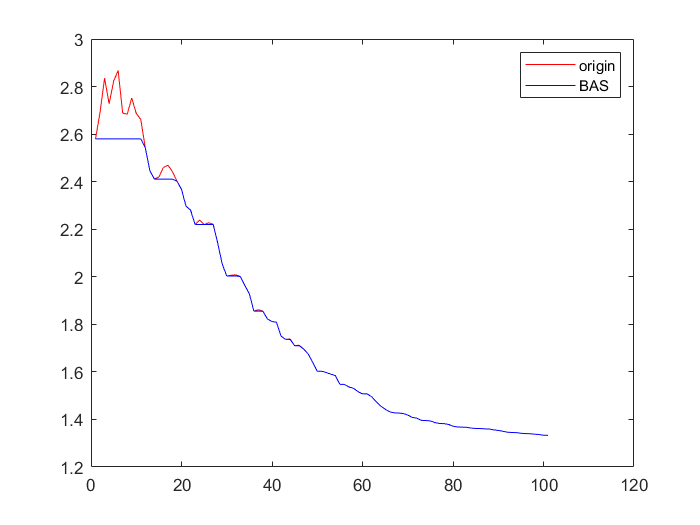

plot(1:n+1,originStore,"Color",'r');
hold on
plot(1:n+1,fbestStore,"Color",'b');
legend('origin','BAS')

a = 1

a = 1

b = 2

b = 2

disp(['输出',a,b])

输出


function y = f(x)
y = norm(x);
end